clear
clf

% 1. Color Gamut
load("Dell.mat")
load("Inkjet.mat")

plot_chrom(XYZdell, 'blue')
plot_chrom(XYZinkjet, 'red')

**Answer:**

Red: They're both about the same in ability to reproduce red.

Green: The inkjet should be better at reproducing green, but neither of them are particularly good.

Blue: The dell should be better at reproducing blue.

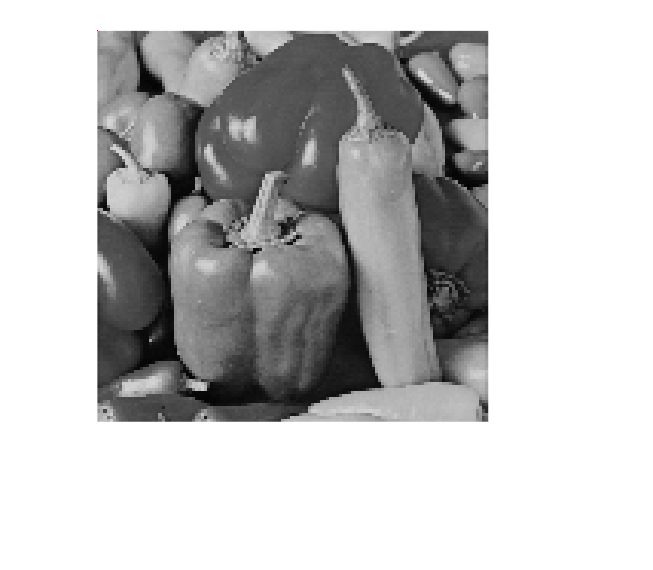

% 2. Mathematical metrics

% 2.1
peppers_gray = im2double(imread("peppers_gray.tif"));

% 2.1.1
peppers_gray_nearest = imresize(imresize(peppers_gray,0.25,'nearest'),4,'nearest');
imshow(peppers_gray_nearest)

mysnr(peppers_gray, abs(peppers_gray-peppers_gray_nearest))

ans = 17.0956

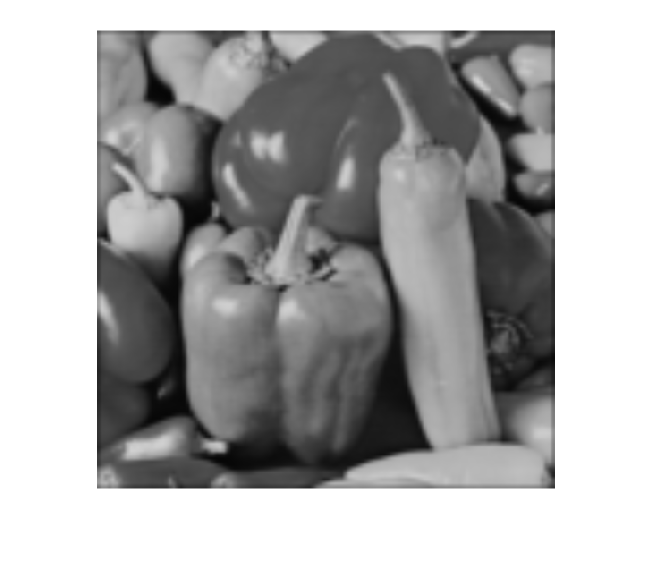


peppers_gray_bilinear = imresize(imresize(peppers_gray,0.25,'bilinear'),4,'bilinear');
imshow(peppers_gray_bilinear)

mysnr(peppers_gray, abs(peppers_gray-peppers_gray_bilinear))

ans = 18.8922

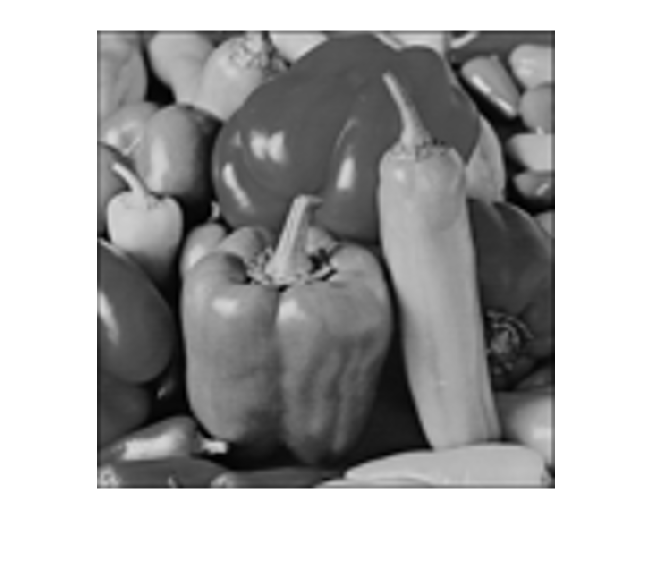


peppers_gray_bicubic = imresize(imresize(peppers_gray,0.25,'bicubic'),4,'bicubic');
imshow(peppers_gray_bicubic)

mysnr(peppers_gray, abs(peppers_gray-peppers_gray_bicubic))

ans = 19.8538

**Answer:** They are pretty similar, but the third is the best, which is also the result from SNR.

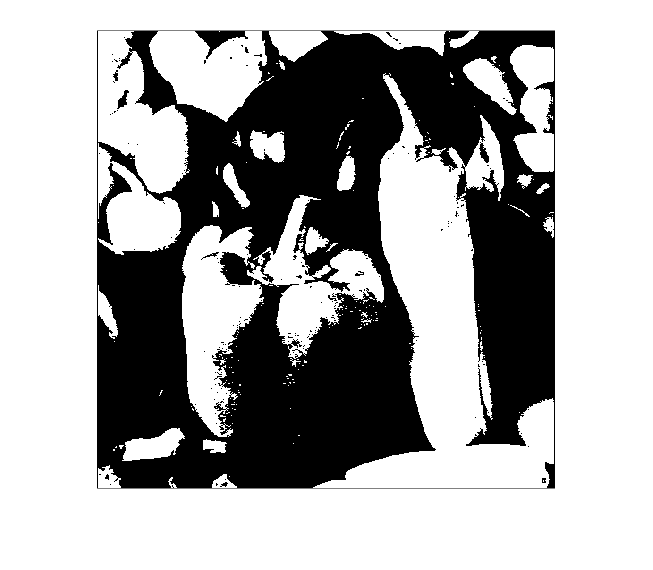

% 2.1.2
peppers_halftone = im2double((peppers_gray >= 0.5));
imshow(peppers_halftone)

mysnr(peppers_gray, abs(peppers_gray-peppers_halftone))

ans = 2.9721

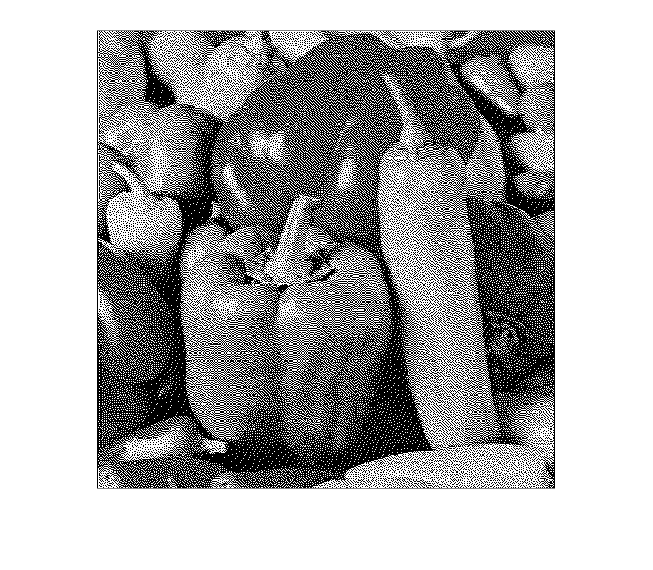


peppers_dither = im2double(dither(peppers_gray));
imshow(peppers_dither)

mysnr(peppers_gray, abs(peppers_gray-peppers_dither))

ans = 0.4112

**Answer:** We do not believe that SNR can be trusted in this case. The second image appears better to the human eye but has a lower SNR value. For changing the halftone value, all values other than 0.5 look worse but have higher SNR (at least for <0.5)

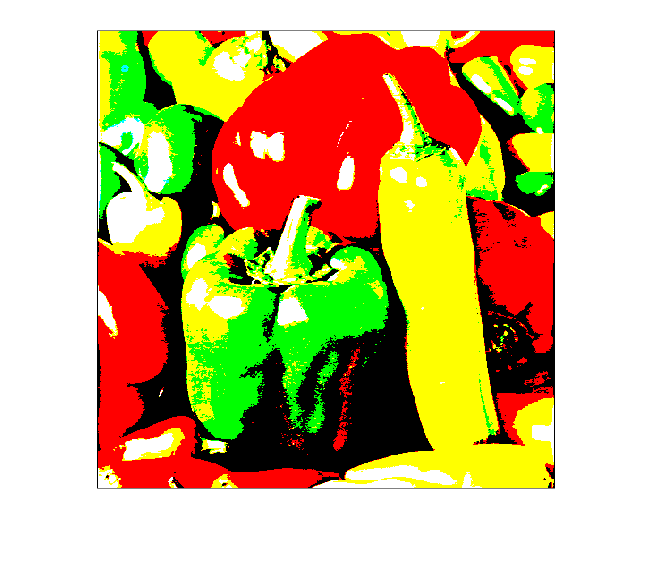

% 2.2
peppers_color = im2double(imread("peppers_color.tif"));

for channel = 1:3
    peppers_colorhalftone(:,:,channel) = im2double((peppers_color(:,:,channel) >= 0.5));
end
imshow(peppers_colorhalftone)

mysnr(peppers_color, abs(peppers_color-peppers_colorhalftone))

ans = 4.3188

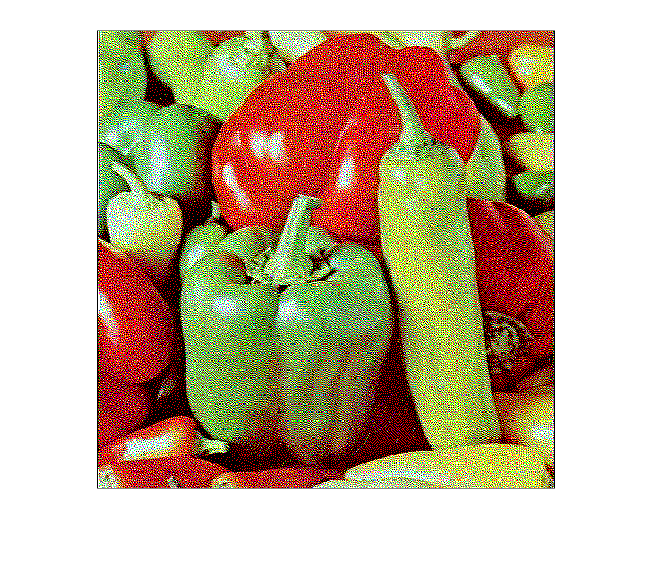


for channel = 1:3
    peppers_colordither(:,:,channel) = double(dither(peppers_color(:,:,channel)));
end
imshow(peppers_colordither)

mysnr(peppers_color, abs(peppers_color-peppers_colordither))

ans = 1.3304


peppers_lab = rgb2lab(peppers_color);
peppers_labhalftone = rgb2lab(peppers_colorhalftone);
peppers_labdither = rgb2lab(peppers_colordither);

deltaE = sqrt((peppers_lab(:,:,1) - peppers_labhalftone(:,:,1)).^2 + (peppers_lab(:,:,2) - peppers_labhalftone(:,:,2)).^2 + (peppers_lab(:,:,3) - peppers_labhalftone(:,:,3)).^2);
mean(mean(deltaE))

ans = 50.1577

max(max(deltaE))

ans = 120.1919

deltaE = sqrt((peppers_lab(:,:,1) - peppers_labdither(:,:,1)).^2 + (peppers_lab(:,:,2) - peppers_labdither(:,:,2)).^2 + (peppers_lab(:,:,3) - peppers_labdither(:,:,3)).^2);
mean(mean(deltaE))

ans = 72.8423

max(max(deltaE))

ans = 203.6272

**Answer:** If the dithered color image is still perceived to be better, neither SNR nor delta E seem to agree.

% 3. Mathematical metrics involving HVS
for channel = 1:3
    hvs_halftone(:,:,channel) = snr_filter(peppers_color(:,:,channel), peppers_color(:,:,channel)-peppers_colorhalftone(:,:,channel));
end
mean(hvs_halftone)

ans = 4.2630


for channel = 1:3
    hvs_dither(:,:,channel) = snr_filter(peppers_color(:,:,channel), peppers_color(:,:,channel)-peppers_colordither(:,:,channel));
end
mean(hvs_dither)

ans = 13.1627

Now it says that the dither is better, which we agree with.


for channel = 1:3
    hvs_rgb(:,:,channel) = MFTsp(peppers_color(:,:,channel));
end

Not enough input arguments.

Error in MFTsp (line 8)
F=MTF(N,d,dis);

hvs_lab = rgb2lab(hvs_rgb);

% deltaE = sqrt((peppers_lab(:,:,1) - peppers_labhalftone(:,:,1)).^2 + (peppers_lab(:,:,2) - peppers_labhalftone(:,:,2)).^2 + (peppers_lab(:,:,3) - peppers_labhalftone(:,:,3)).^2);
% mean(mean(deltaE))
% max(max(deltaE))
% deltaE = sqrt((peppers_lab(:,:,1) - peppers_labdither(:,:,1)).^2 + (peppers_lab(:,:,2) - peppers_labdither(:,:,2)).^2 + (peppers_lab(:,:,3) - peppers_labdither(:,:,3)).^2);
% mean(mean(deltaE))
% max(max(deltaE))